**I have implemented several functions for the convenience of coding and those are shown at the end of this report.**

- Obtaining the plot of the sinusoidal signal, $\mathrm{𝑦}\left(\mathrm{𝑡}\right)=\mathrm{𝐴}\ast \mathrm{𝐶𝑜𝑠}\left(2\ast \mathrm{𝜋}\ast \mathrm{𝑓}\ast \mathrm{𝑡}\right)$

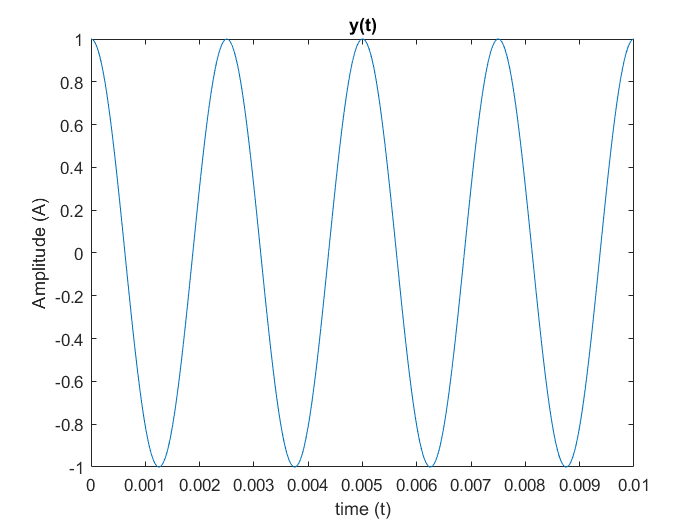

%Q1
A = 1;     %a.u
f = 400;   %Hz
t = 0:1e-8:0.01;        %time axis
y = A*cos(2*pi*f*t);    %original signal
%plotting
fig(t,y,'y(t)',true)

2. Finding the Nyquist sampling frequency (fnq)

%Q2
f = 400;     %signal frequency
fs = 2*f;    %sampling frequency
fnq = fs   %Nyquist sampling frequency

fnq = 800

Therefore the Nyquist sampling frequency (fnq) = 800 Hz 

3.  Sampled signal $\bar{y\left(t\right)} \;=y\left(t\right)\times \delta_{\mathrm{Ts}} \left(t\right)$     ; where $y\left(t\right)$ is the signal and $\delta_{\textrm{Ts}} \left(t\right)$ is the puse train

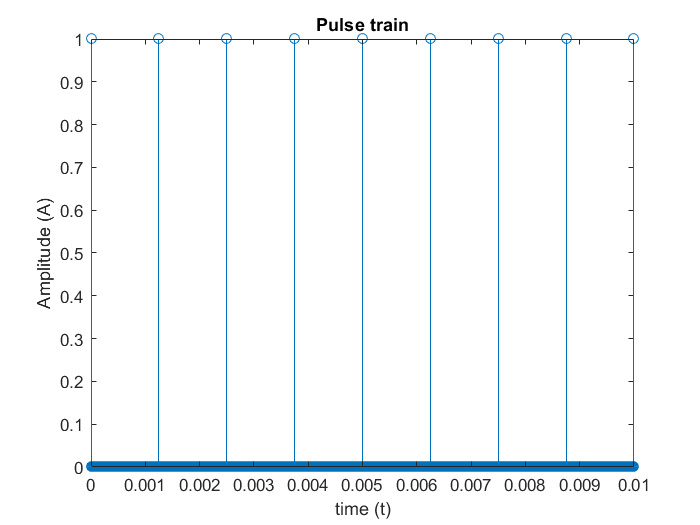

%Q3
fs = fnq;       %nyquist freq
delta_Ts = Delta(t,fs);     %pulse train
fig(t,delta_Ts,'Pulse train',false)

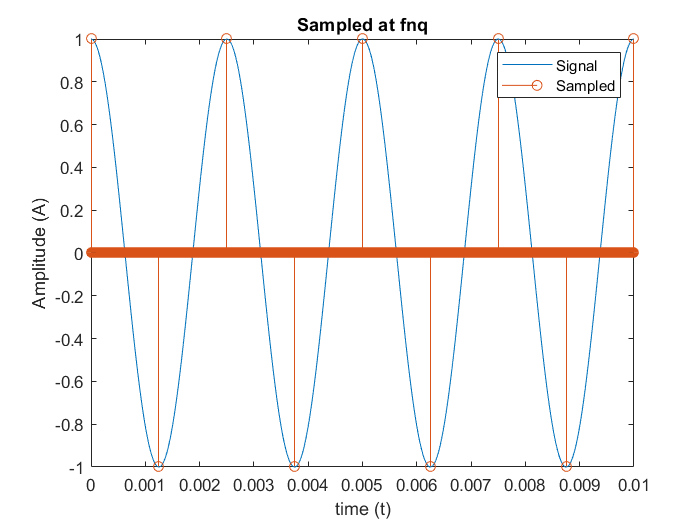

y_dash = y.*delta_Ts;       %sampled signal
fig(t,y,'y(t)',true)
hold on;
fig(t,y_dash,'Sampled at fnq',false);
legend('Signal','Sampled')
hold off;

4. Sampling the signal at different frequencies and comparing.

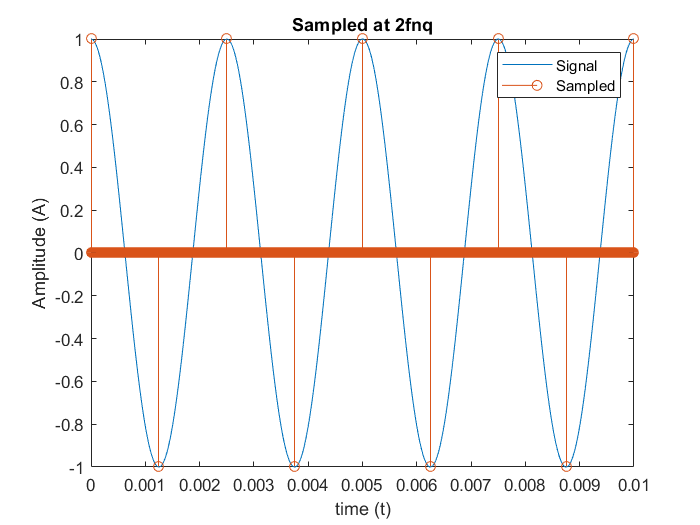

%Q4
%at 2*nyquist freq
fs = 2*fnq;
delta_Ts_bd = Delta(t,fs);
y_dash_bd = y.*delta_Ts_bd;
fig(t,y,'y(t)',true)
hold on;
fig(t,y_dash_bd,'Sampled at 2fnq',false);
legend('Signal','Sampled')
hold off;

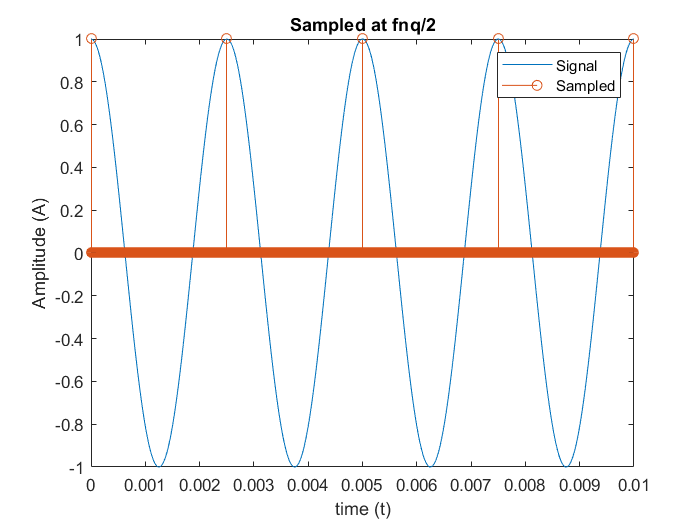

%at 0.5*nyquist freq
fs = fnq/2;
delta_Ts_hf = Delta(t,fs);
y_dash_hf = y.*delta_Ts_hf;
fig(t,y,'y(t)',true)
hold on;
fig(t,y_dash_hf,'Sampled at fnq/2',false);
legend('Signal','Sampled')
hold off;

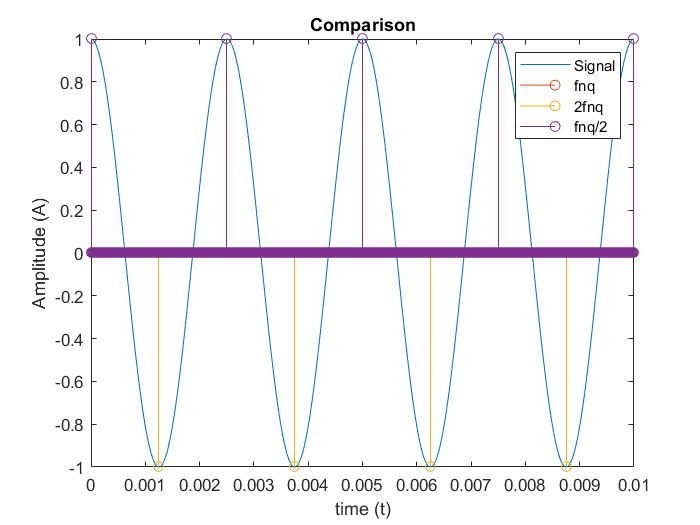

%comparison
fig(t,y,'',true)
hold on;
fig(t,y_dash,'',false);
fig(t,y_dash_bd,'',false);
fig(t,y_dash_hf,'Comparison',false);
legend('Signal','fnq','2fnq','fnq/2')
hold off;

Using the above plots and the compared plot we can observe that:

- the signal sampled at 2fnq is visually seems to be similar to that at fnq as the added samples are directed to zeros.

- but at fnq/2, it reduces a part of the signal.

so, from that we can conclude that the Nyquist frequency(fnq) is the minimum frequency that is suitable as the sampling frequency in order to recover the original signal.

5.  SNqR = $\frac{\mathrm{Signal}\;\mathrm{Power}}{Q-\mathrm{noise}\;\mathrm{Power}}$   = $\frac{\bar{y^2 \left(t\right)} }{\left(\frac{{m_p }^2 }{3L^2 }\right)}$  =   $\frac{3L^2 \bar{y^2 \left(t\right)} }{{m_p }^2 }$

    $\mathrm{SNqR}$    = $10\log \left(\textrm{SNqR}\right)=10\log \frac{3L^2 \bar{y^2 \left(t\right)} }{{m_p }^2 }$ $\ge$ 25dB

    so,     ${\textrm{SNqR}}_{\min }$    = 25dB

    since signal power = $\bar{y^2 \left(t\right)}$ = $\frac{A^2 }{2}$  (as y is a sinusoidal)     and $m_p =A$ $\colon$

                log$\frac{3L^2 }{2}$ = 2.5   and     $L=2^{n_b }$

%Q5
L_min = sqrt((2/3)*10^2.5)

L_min = 14.5196

nb_min = log2(L)

nb_min = 4

Therefore;

- Minimum number of bits (nb)  required per a sample = 4 bits

- Minimum number of quantization levels (L)    = 16 levels    (as nb = 4 and for the convenience of the process)

6. Function is defined accordingly.

%Q6
Q_val = quant_val(0.3,5,2)  %getting quantized value

Q_val = 0.5000

7. Sampling and quantizing at 8fnq

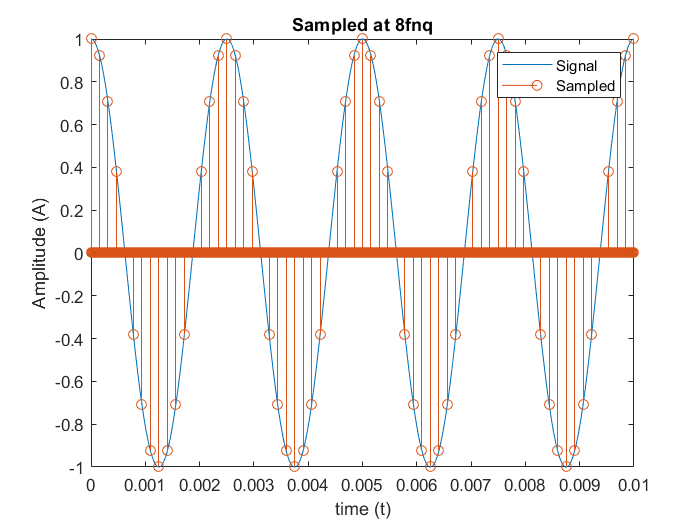

%Q7
%sampling
fs = 8*fnq;
delta_Ts_oct = Delta(t,fs);
y_dash_oct = y.*delta_Ts_oct;
fig(t,y,'y(t)',true)
hold on;
fig(t,y_dash_oct,'Sampled at 8fnq',false);
legend('Signal','Sampled')
hold off;

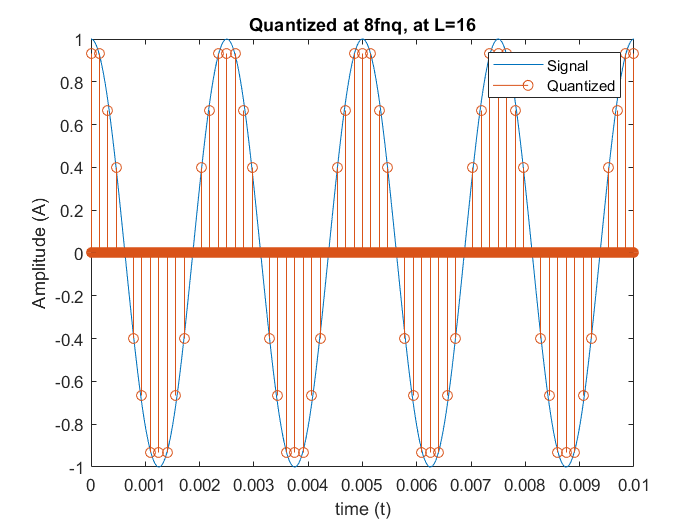

%quantizing
L = 16;
Q_y = quant_f(y_dash_oct,L,1);  %quantized signal function
fig(t,y,'y(t)',true)
hold on;
fig(t,Q_y,'Quantized at 8fnq, at L=16',false);
legend('Signal','Quantized')
hold off;

8. Quantizing the sampled signal in above part for L*2 and L/2 quantization levels.

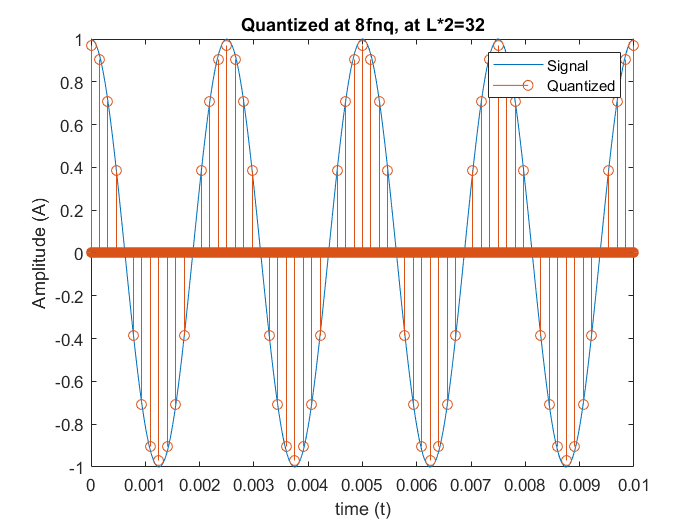

%Q8
%L*2
Q_y_db = quant_f(y_dash_oct,L*2,1);
fig(t,y,'y(t)',true)
hold on;
fig(t,Q_y_db,'Quantized at 8fnq, at L*2=32',false);
legend('Signal','Quantized')
hold off;

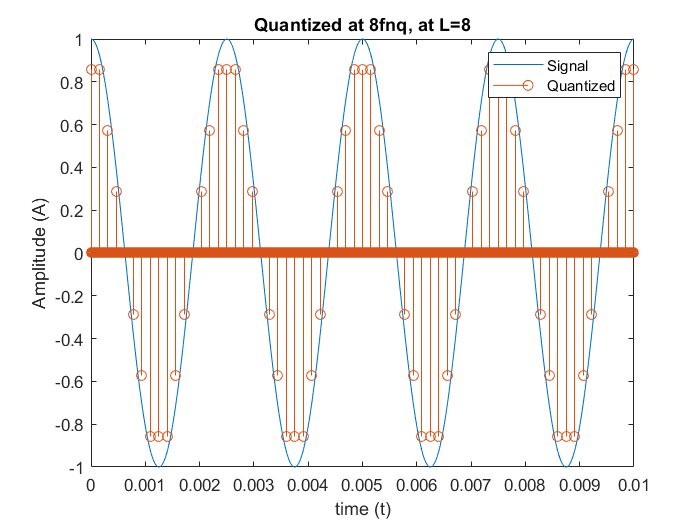

%L/2
Q_y_hf = quant_f(y_dash_oct,L/2,1);
fig(t,y,'y(t)',true)
hold on;
fig(t,Q_y_hf,'Quantized at 8fnq, at L=8',false);
legend('Signal','Quantized')
hold off;

From the above graphs we can observe that,

- when L=32 (>Lmin=16) all the points and information are preserved.

- when L=8 (<Lmin=16) peak values are lost and so that the signal cannot be recovered.

so the Lmin=16 is the necessity for the SNqR<=25dB and 25dB is a better margin to avoid the quantization noise.

FUNCTIONS

function [delta_Ts] = Delta(t,fs)    %pulse train
Ts = 1/fs;
delta_Ts = zeros(size(t));
ts = t(end)/(length(t)-1);
delta_Ts(1:Ts/ts:end) = 1;
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function fig(t,y,topic,cnt)   %getting figures
if cnt 
    plot(t,y);
else 
    stem(t,y);
end
xlabel("time (t)");
ylabel("Amplitude (A)");
title(topic);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [Q_val] = quant_val(val,L,mp)
deltaV = (2*mp)/(L-1);
lvls=-mp:deltaV:mp;     %levels range
for i=lvls
    if i>val
        break
    end
    temp=i;
end
if i==temp
    Q_val=(i+lvls(length(lvls)-1))/2;
else
    Q_val=(temp+i)/2;
end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [Q_y] = quant_f(y,L,mp)
Q_y = zeros(size(y));
for i=1:length(y)
    Q_y(i) = quant_val(y(i),L,mp);
end
end